% Bacterial growth rate

% quad
t=0:7; % times for integration
for i = 1:length(t) % the loop for integration by the quard command
    q(i) = quad('0.6931*10*2.^t',0,t(i));
end

fprintf('\n Bacterial amount\n Hour Cell\n'); %title for resulting table


 Bacterial amount
 Hour Cell


fprintf('%5.0f %8.0f\n',[floor(t);q]); %displays resulting table

     0        0
     1       10
     2       30
     3       70
     4      150
     5      310
     6      630
     7     1270


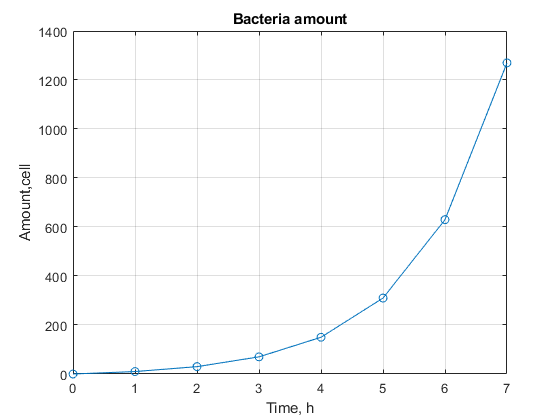

plot(t,q,'-o') %plot the graph
title('Bacteria amount')
xlabel('Time, h'),ylabel('Amount,cell')
grid


%Simpsons
n = 1000;
a = 0;
b = 7;
dt = (b-a)/(n-1);
t = a:dt:b;
f = 0.6931*10*2.^t;
N7 = floor(dt*sum(f(1:end-1)));
fprintf('\nBacterial amount after 7 hours by the\n')


Bacterial amount after 7 hours by the


fprintf('Left Riemann N = %5.0f Simpson N = %5.0f\n', N7, q(end))

Left Riemann N =  1266 Simpson N =  1270
